clear
clf
clc
load('Project_Data.mat')

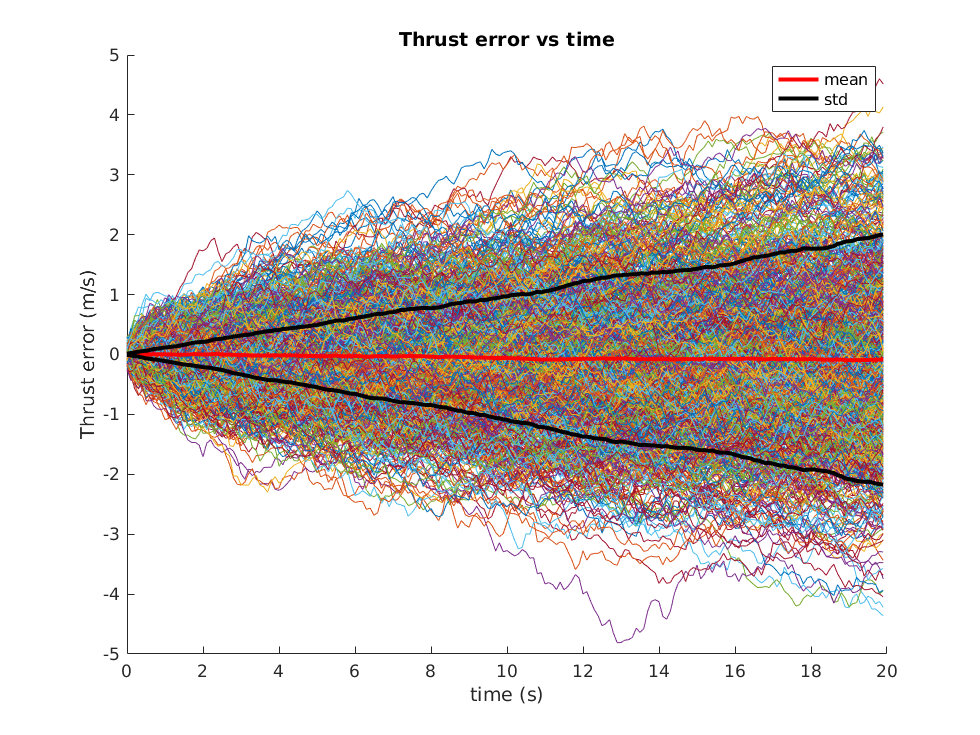

%step 1
figure
hold on
t = 0:0.1:19.9;

thrust_mean = zeros(200,1);
thrust_var = zeros(200,1);

for i = 1:200
    thrust_mean(i,1) = mean(thrust(i,:));
    thrust_var(i,1) = var(thrust(i,:));
end




for i = 1:1000
    plot(t,thrust(:,i),'HandleVisibility','off')
end

plot(t,thrust_mean,'r','LineWidth',3)
plot(t,thrust_mean + thrust_var,'k','LineWidth',3)
plot(t,thrust_mean - thrust_var,'k','LineWidth',3)
title("Thrust error vs time")
xlabel("time (s)")
ylabel("Thrust error (m/s)")
legend("mean","std")

q = thrust_var(end)/t(end)

q = 0.1050

step 2

Thrust error can be modeled as brownian motion for the velocity state of the rocket.

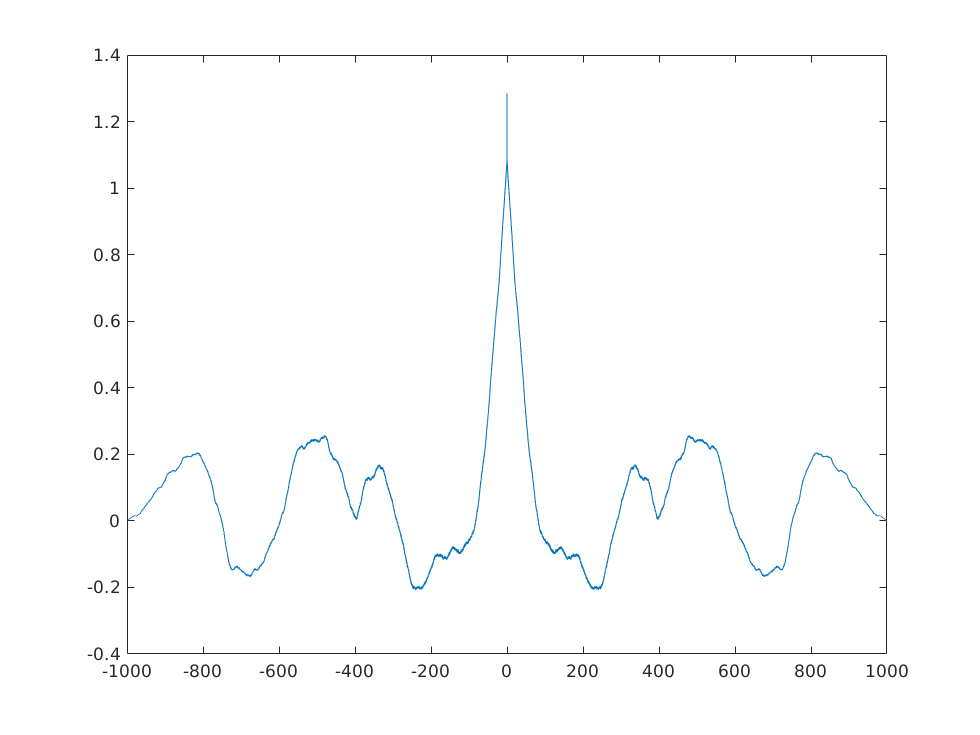

%step 3
figure
hold off
%plot(radar_alt)

%ergotic stationary random process
[r, lags] = xcorr(radar_alt,'biased');
plot(lags*0.1, r)

R = 1.28-1.08;
fogmvar = 1.08;
tau = 45;

The radar altimeter error can be descriped as a FOGM added to white noise with the following block diagram:

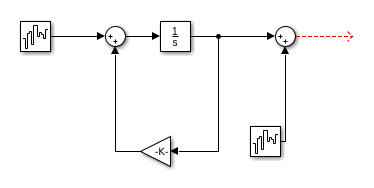

%step 4
Q = [0,0,0; 0 q 0; 0 0 2*fogmvar/tau]

Q =          0         0         0
         0    0.1050         0
         0         0    0.0480


%step 5
F = [0 1 0;...
     0 0 0;...
     0 0 1/tau]

F =          0    1.0000         0
         0         0         0
         0         0    0.0222


%step 6
B = [0;1;0]

B =      0
     1
     0


%step 7
H = [1 0 1]

H =      1     0     1


%step 8
sys = ss(F,B,H,[]);
d_sys = c2d(sys, 0.1);
Q_d = CalculateQdVanLoan(F,eye(3),Q,0.1);
R_c = chol(R)';
Qd_c = chol(Q_d)';
load('SpaceX_Filter_Structure.mat');
m.Bd = d_sys.B;
m.Phi = d_sys.A;
m.Qd = Q_d;
m.Qd_chol = Qd_c;
m.H = H;
m.R = R;
m.R_chol = R_c;
m.update_interval = 0.1;
save('SpaceX_Filter_Structure.mat',"m")

Step 9

Step 11:

The left most rocket jumps around between timesteps. It behaves like a FOGM process with added white noise. The middle rocket more smoothly follows the trajectory of the real rocket. The covariance bar always increases with time.

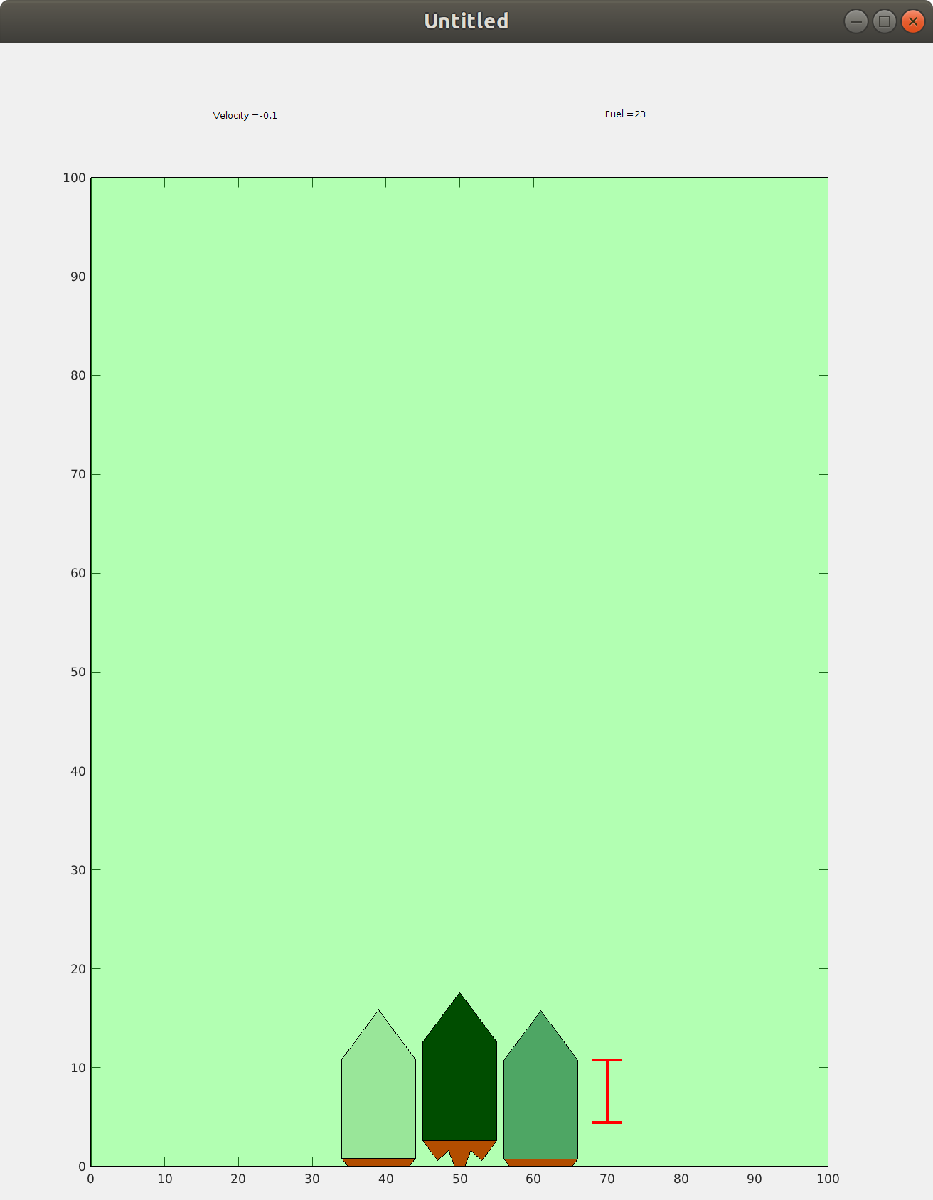

%step 12
load("SpaceX_Winning_Inputs.mat")

montecarlotime = 0:0.1:length(inputs_saved)/10;

alt_mean = zeros(1,length(inputs_saved)+1);
alt_mean(1) = x_init(1);
x_prop = x_init;
alt_std = zeros(1,length(inputs_saved)+1);
P_prop = P_init;
vel_mean = zeros(1,length(inputs_saved)+1);
vel_mean(1) = x_init(2);
vel_std = zeros(1,length(inputs_saved)+1);
bias_mean = zeros(1,length(inputs_saved)+1);
bias_mean(1) = x_init(3);
bias_std = zeros(1,length(inputs_saved)+1);

for i = 2:length(alt_mean)
    x_prop = SpaceX_Prop_Mean(x_prop, m, inputs_saved(i-1));
    alt_mean(i) = x_prop(1);
    P_prop = SpaceX_Prop_Cov(P_prop,m);
    alt_std(i) = sqrt(P_prop(1,1));
    vel_std(i) = sqrt(P_prop(2,2));
    bias_std(i) = sqrt(P_prop(3,3));
    vel_mean(i) = x_prop(2);
    bias_mean(i)= x_prop(3);
end




realizationsAlt = zeros(1000,length(inputs_saved)+1);
realizationsAlt(:,1) = x_init(1);

realizationsVel = zeros(1000,length(inputs_saved)+1);
realizationsVel(:,1) = x_init(2);

realizationsBias = zeros(1000,length(inputs_saved)+1);
for i = 1:1000
    x_prop = x_init;
    for j = 2:length(alt_mean)
        x_prop = SpaceX_Prop_States(x_prop,m,inputs_saved(j-1));
        realizationsAlt(i,j) = x_prop(1);
        realizationsVel(i,j) = x_prop(2);
        realizationsBias(i,j) = x_prop(3);
    end
end
x_prop

x_prop =    -1.0590
   -1.0880
   -1.4715


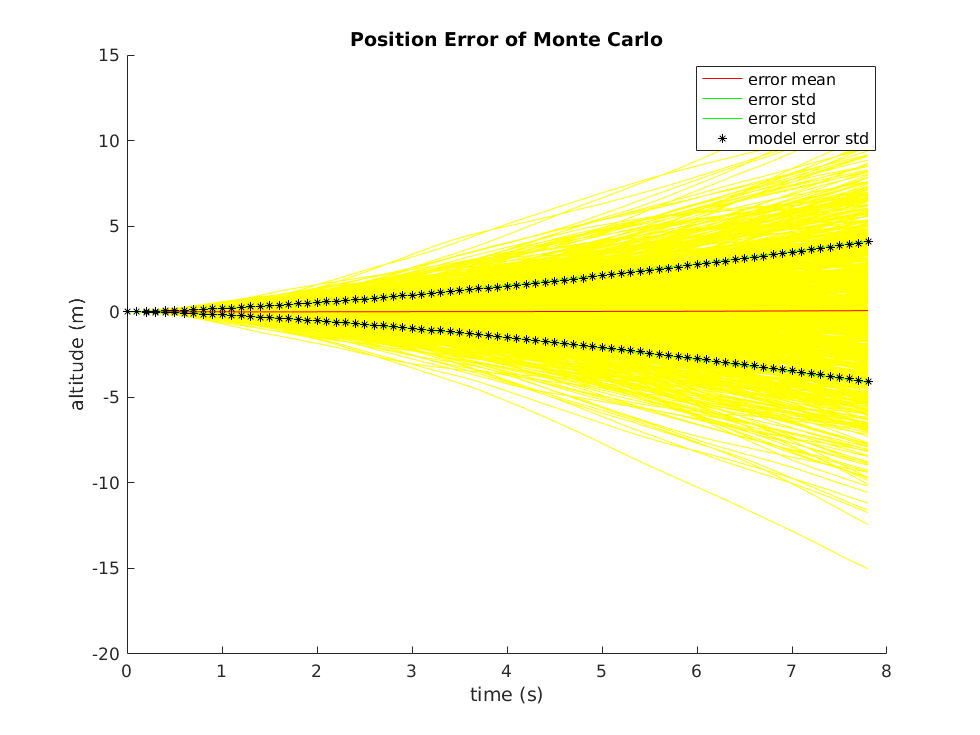


figure
hold on
for i = 1:1000
    plot(montecarlotime,realizationsAlt(i,:)-alt_mean,'y','HandleVisibility','off')
end
realizationsAlt_mean = mean(realizationsAlt-alt_mean,1);
plot(montecarlotime,realizationsAlt_mean,'r')
realizationsAlt_std = std(realizationsAlt-alt_mean,1);
plot(montecarlotime, realizationsAlt_std,'g')
plot(montecarlotime, -1*realizationsAlt_std,'g')
plot(montecarlotime, alt_std,'*k')
plot(montecarlotime, -1*alt_std,'*k')


title("Position Error of Monte Carlo")
xlabel("time (s)")
ylabel("altitude (m)")
legend("error mean","error std","error std","model error std")

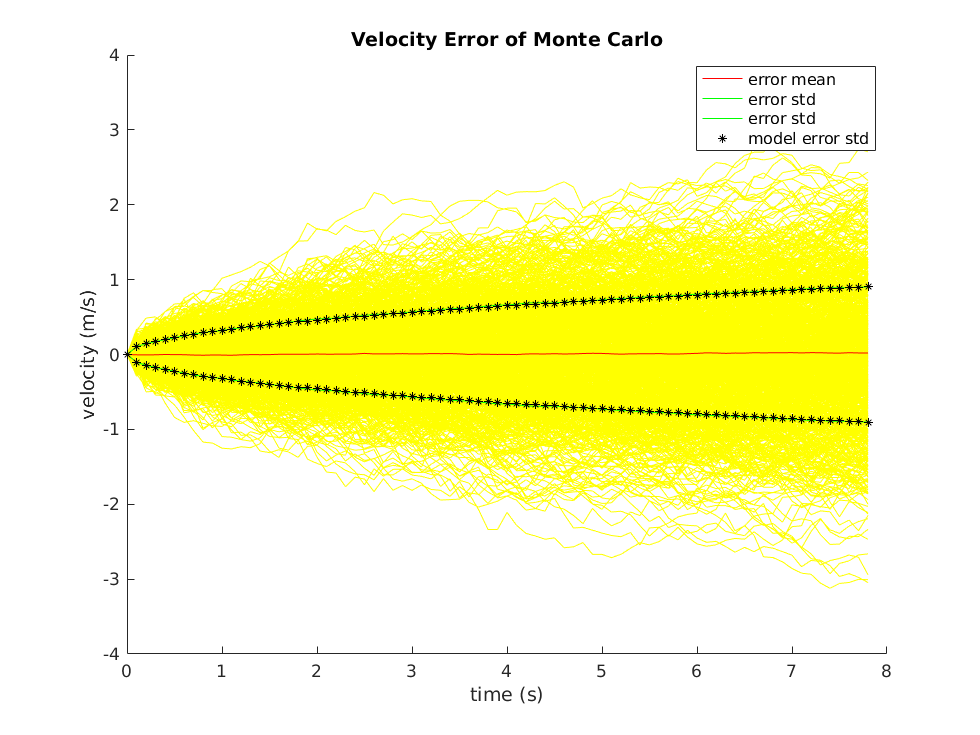

%legend("model mean")

figure
hold on
for i = 1:1000
    plot(montecarlotime,realizationsVel(i,:)-vel_mean,'y','HandleVisibility','off')
end
realizationsVel_mean = mean(realizationsVel-vel_mean,1);
plot(montecarlotime,realizationsVel_mean,'r')
realizationsVel_std = std(realizationsVel-vel_mean,1);
plot(montecarlotime, realizationsVel_std,'g')
plot(montecarlotime, -1* realizationsVel_std,'g')
plot(montecarlotime, vel_std,'*k')
plot(montecarlotime, -1*vel_std,'*k')

%plot(montecarlotime,vel_mean,'b')

title("Velocity Error of Monte Carlo")
xlabel("time (s)")
ylabel("velocity (m/s)")
legend("error mean","error std","error std","model error std")

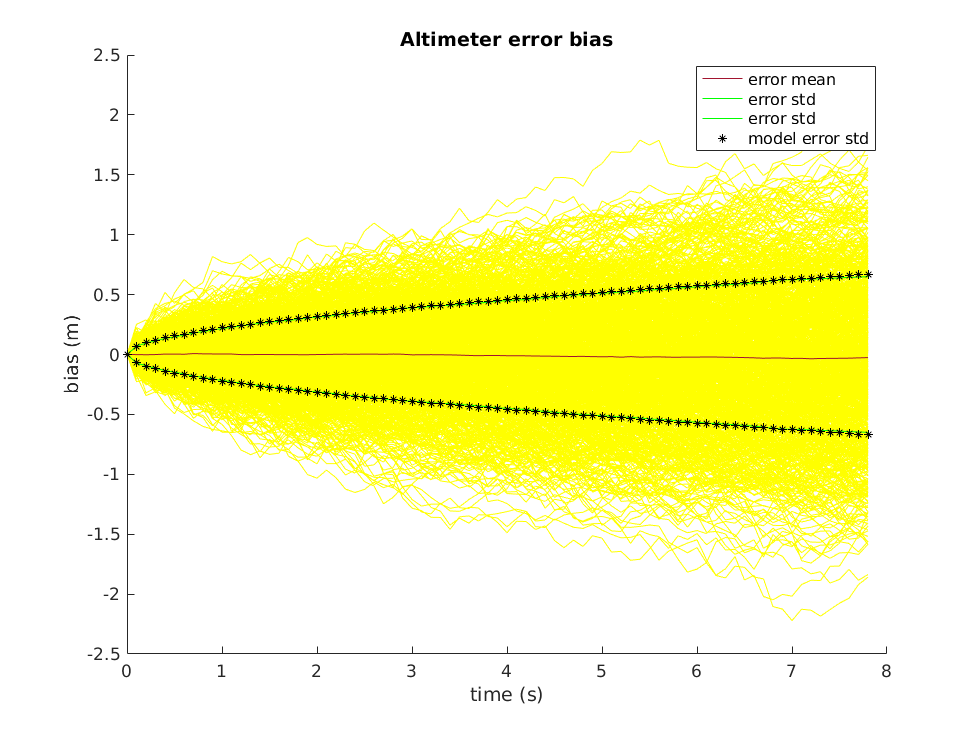

%legend("model mean")

figure
hold on
for i = 1:1000
    plot(montecarlotime,realizationsBias(i,:),'y','HandleVisibility','off')
end

reaizationsBias_mean = mean(realizationsBias,1);
plot(montecarlotime,reaizationsBias_mean)
realizationsBias_std = std(realizationsBias,1);
plot(montecarlotime, realizationsBias_std,'g')
plot(montecarlotime, -1*realizationsBias_std,'g')
plot(montecarlotime, bias_std,'*k')
plot(montecarlotime, -1*bias_std,'*k')
legend("error mean","error std","error std","model error std")

%plot(montecarlotime,bias_mean,'b')
title("Altimeter error bias")
xlabel("time (s)")
ylabel("bias (m)")

%legend("model mean")

%step 13
wins = zeros(1,1000);
for i = 1:1000
    if abs(realizationsAlt(i,end)) < 1 & abs (realizationsVel(i,end))<1
        wins(i) = 1;
    end
end

sum(wins)

ans = 143

There were 143 successful landings on this monte carlo simulation